# Oxygen System

## INITIALIZE UQLAB

Clear all variables from the workspace, set the random number generator for reproducible results, and initialize the UQLab framework:

clc; clear all; close all;
rng(100,'twister');
uqlab;

Copyright 2013-2024, Stefano Marelli and Bruno Sudret.
This is UQLab, version 2.1
UQLab is distributed under the BSD 3-clause open source license available at: 
<a href="https://uqlab.com/license">https://uqlab.com/license</a>.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## COMPUTATIONAL MODEL

ModelOpts.mString = 'X(:,1).*X(:,2).*X(:,3).*X(:,4).*X(:,5).*X(:,6).*X(:,7).*X(:,8).*X(:,9).*X(:,10).*X(:,11).*X(:,12).*X(:,13).*X(:,14).*X(:,15).*X(:,16)'; 
ModelOpts.isVectorized = true;

myModel = uq_createModel(ModelOpts);

Type `help uq_DampedOscillator` for information on the model structure as well as the description of each variable.

## PROBABILISTIC INPUT MODEL

The probabilistic input model consists of eight independent lognormal random variables.

Define an INPUT object using the following marginals:

InputOpts.Marginals(1).Name = 'X1';  %failure of Oxygen Cylinder
InputOpts.Marginals(1).Type = 'Exponential';
InputOpts.Marginals(1).Moments = 1/0.001.*ones(1,2);

InputOpts.Marginals(2).Name = 'X2';  %failure of Pressure Transducer/Gauge
InputOpts.Marginals(2).Type = 'Exponential';
InputOpts.Marginals(2).Moments = 1/0.0055.*ones(1,2);

InputOpts.Marginals(3).Name = 'X3';  %failure of Manual Isolation Valve 
InputOpts.Marginals(3).Type = 'Exponential';
InputOpts.Marginals(3).Moments = 1/0.0059.*ones(1,2);

InputOpts.Marginals(4).Name = 'X4';  %  failure of Storage Regulator
InputOpts.Marginals(4).Type = 'Exponential';
InputOpts.Marginals(4).Moments = 1/0.0022.*ones(1,2);

InputOpts.Marginals(5).Name = 'X5';  % failure of Discharge Equipment 
InputOpts.Marginals(5).Type = 'Exponential';
InputOpts.Marginals(5).Moments = 1/0.00005.*ones(1,2);

InputOpts.Marginals(6).Name = 'X6';  % failure of Storage to Cockpit Piping
InputOpts.Marginals(6).Type = 'Exponential';
InputOpts.Marginals(6).Moments = 1/0.00005.*ones(1,2);

InputOpts.Marginals(7).Name = 'X7';  % failure of Distribution manifold
InputOpts.Marginals(7).Type = 'Exponential';
InputOpts.Marginals(7).Moments = 1/0.00005.*ones(1,2);

InputOpts.Marginals(8).Name = 'X8';  % failure of Distribution manifold
InputOpts.Marginals(8).Type = 'Exponential';
InputOpts.Marginals(8).Moments = 1/0.00005.*ones(1,2);

InputOpts.Marginals(9).Name = 'X9';  % failure of Storage Box Assembly
InputOpts.Marginals(9).Type = 'Exponential';
InputOpts.Marginals(9).Moments = 1/0.00001.*ones(1,2);

InputOpts.Marginals(10).Name = 'X10';  % failure of face mask pipeline
InputOpts.Marginals(10).Type = 'Exponential';
InputOpts.Marginals(10).Moments = 1/0.00005.*ones(1,2);

InputOpts.Marginals(11).Name = 'X11';  % failure of face mask
InputOpts.Marginals(11).Type = 'Exponential';
InputOpts.Marginals(11).Moments = 10.*ones(1,2);

InputOpts.Marginals(12).Name = 'X12';  % failure of cockpit pressure gague
InputOpts.Marginals(12).Type = 'Exponential';
InputOpts.Marginals(12).Moments = 1/0.0055.*ones(1,2);

InputOpts.Marginals(13).Name = 'X13';  % failure of detecting decompression
InputOpts.Marginals(13).Type = 'Exponential';
InputOpts.Marginals(13).Moments = 100.*ones(1,2);

InputOpts.Marginals(14).Name = 'X14';  %p failure of toxic gas sensor
InputOpts.Marginals(14).Type = 'Exponential';
InputOpts.Marginals(14).Moments = 1/0.000001.*ones(1,2);

InputOpts.Marginals(15).Name = 'X15';  % failure of Detecting toxic gas/smoke
InputOpts.Marginals(15).Type = 'Exponential';
InputOpts.Marginals(15).Moments = 100.*ones(1,2);

InputOpts.Marginals(16).Name = 'X16';  % failure of using face mask
InputOpts.Marginals(16).Type = 'Exponential';
InputOpts.Marginals(16).Moments = 100.*ones(1,2);


Create an INPUT object based on the defined marginals:

myInput = uq_createInput(InputOpts);

## RELIABILITY ANALYSIS

Failure event is defined as $g(\mathbf{x}) \leq 0$. The failure probability is then defined as $P_f = P[g(\mathbf{x}) \leq 0]$.

## Monte Carlo simulation (MCS)

Select the Reliability module and the Monte Carlo simulation (MCS) method:

MCSOpts.Type = 'Reliability';
MCSOpts.Method = 'MCS';

Specify the sample size and the target coefficient of variation (CoV):

MCSOpts.Simulation.BatchSize = 5e3;
MCSOpts.Simulation.MaxSampleSize = 1e4;
MCSOpts.Simulation.TargetCoV = 5e-2;

Run the Monte Carlo simulation:

MCSAnalysis = uq_createAnalysis(MCSOpts);

Print out a report of the results:

uq_print(MCSAnalysis)

Create a graphical representation of the results:


Starting Crude Monte Carlo Analysis...

         Current : NaN	
         Target  : 0.050000

MC: Finished.
 

---------------------------------------------------
Monte Carlo simulation
---------------------------------------------------
Pf               0000             
Beta             Inf              
CoV              NaN              
ModelEvaluations 10000            
PfCI             [0.0000e+00 0.0000e+00]
BetaCI           [Inf        Inf       ]
---------------------------------------------------



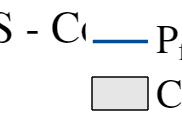

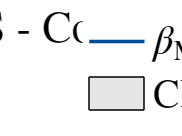

uq_display(MCSAnalysis)